# Numerical Simulation of a COVID-19 SIR Model

  Jiaen Qi

## I. Prelude

A mathematical model is a system using mathematical concepts, equations, or simulations to describe relationships among variables and predict behaviors over time. In life sciences, mathematical models help scientists quantify complex biological processes, from the growth of populations to the spread of diseases.

These models enable researchers to analyze biological systems that are often too complex to study directly. For instance, epidemiological models like the SIR model can simulate how infectious diseases spread, helping public health officials predict outbreaks and design control strategies. In ecology, models help predict how species interact with one another and respond to environmental changes. 

## II. Introduction of *SIR*

Assume the total population 𝑁 is constant, and divide 𝑁 into three groups: susceptibles, infectives, and recovered/removed. 

#### Then we denote: 

$S\left(t\right)$ = population of the susceptible at time 𝑡; 

$I\left(t\right)$ = population of the infective at time 𝑡; 

$R\left(t\right)$ = population of the recovered at time 𝑡.

#### We define: 

- 
$$\frac{dS}{dt} = -\beta \frac{I}{N} S$$


- 
$$\frac{dI}{dt} = \beta \frac{I}{N} S - \gamma I$$


- 
$$\frac{dR}{dt} = \gamma I$$


#### where: 

- $\beta \frac{1}{N}S$: the rate of change of susceptible individuals (S) being infected (I). 

- $\beta$: infectiousness

- N: population size

- $\frac{I}{N}$: proportion of infectious individuals

- $S$: number of susceptibles

- $\gamma$: recovery rate

- $I$: number of currently infected individuals

#### Note: 

There is a negative sign "-" in the equation for $\frac{dS}{dt}$ because this term is reducing the susceptible population size. The susceptibles ($S$) are moving into the infected group ($I$). 

There is only one term on the right-hand side of the third equation. It shows the rate of infected people recovering from the disease, and revocery only depends on the current infected group ($I$). 

We can assume $S\left(t\right)+I\left(t\right)+R\left(t\right)=N$is a constant. This shows that the total population $N$ is a fixed number, to avoid situations like new born babies, or people dying, etc... Hence, this works when the timescale is short, when we don't consider natural birth or death, and other things similar. This condition excludes situations impacted by factors irrelevant to our experiment. 

#### We define: 

- 
$$R_0 =\frac{\beta }{\gamma }>1$$
 

#### where:

- $R_0$: the Basic Reproduction Number

- $\frac{\beta }{\gamma }$: the average number of infections caused by one infectious person

Note: $R_0 >1$here means that each infected person could spread the disease to more than 1 person. In that case, the infection would spread rapidly. 

#### Example: 

Rai et al. conducted a study, showing that reproducibility for COVID-19 in India was 2.56 and herd immunity as 61%, in which an exponential growth model was applied to calculate future cases based on cumulative confirmed cases, recovered cases, and death rate over 21 days period. [1]

## III. Simulation

Consider the following situation: people in a small town (total population: 10000) are experiencing the flu season, and today's record shows that 10 people have already recovered, and 200 people are having the flu. Assume that active immunity is obtained once fully recovered, and the newborn and death can be neglected during a short period of time. Here we also assume that the rate of infection when contacting a patient is 75%, and every day a patient has a probability of 15% of becoming fully recovered (rate of recovery). 

### Given: 

- 
$$N=10000$$


- 
$$I\left(0\right)=200$$


- 
$$R\left(0\right)=10$$


- 
$$S\left(0\right)=10000-200-10=9790$$


- 
$$\beta =75%=0\ldotp 75$$


- 
$$\gamma =15%=0\ldotp 15$$


### Codes & Figure:

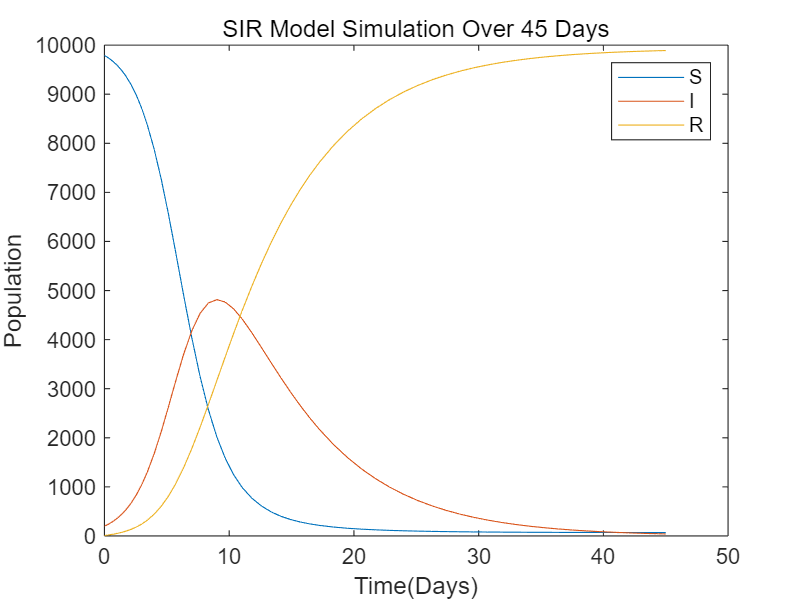

%% Initial Conditions

N = 10000;
S0 = 9790;
I0 = 200;
R0 = 10;
beta = 0.75;
gamma = 0.15;
Y0 = [S0, I0, R0];
tspan = [0 45]; 

% Solve the SIR model using ode45
[t,Y] = ode45(@(t,Y) simple_SIR(t,Y,beta,gamma),tspan,Y0);

% Plot the simulation results
plot(t,Y(:,1),t,Y(:,2),t,Y(:,3))
xlabel('Time(Days)');
ylabel('Population');
title('SIR Model Simulation Over 45 Days');
legend('S', 'I', 'R');

### Analysis: 

Over the 45 days, the simulation result shows:

- A dramatic increase in the infected population initially

- A sharp decrease in susceptibles

- A constant rise in recovered people

The disease spreads quickly at first, with most susceptible people infected. As more people recover, the infection will be slowing down and eventually decreasing. 

In this case, the Basic Reproduction Number $R_0$ is equal to $\frac{0\ldotp 75}{0\ldotp 15}=5$. This shows that each infected person spreads the disease to 5 people on average. 

### What If: 

- 
$$\beta =0\ldotp 10$$


- 
$$\gamma =0\ldotp 15$$


Then $R_0 =\frac{0\ldotp 10}{0\ldotp 15}=0\ldotp 67$, which indicates that each infected person will infect less than 1 person on average. 

#### Codes & Figure:

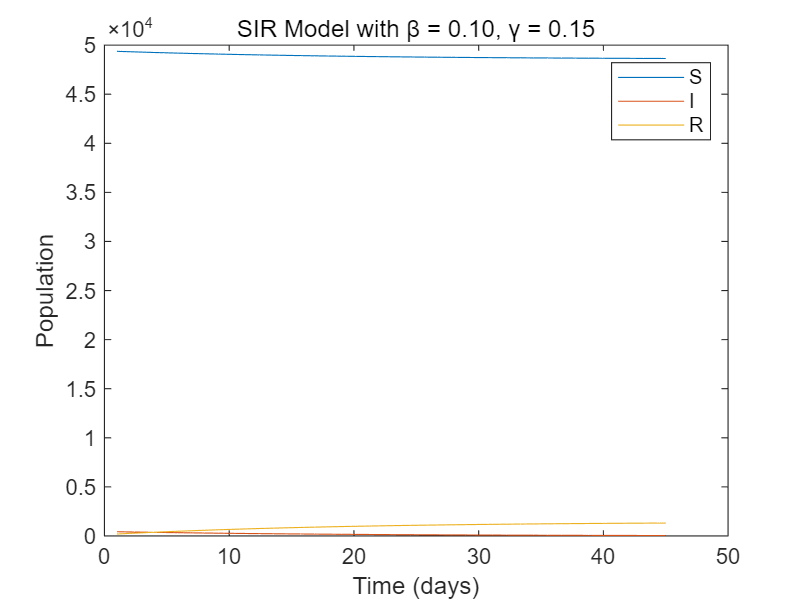

beta2 = 0.10;
gamma2 = 0.15;

% Simulate
[t2,Y2] = ode45(@(t,Y) simple_SIR(t,Y,beta2,gamma2), [1 45], Y0);

% Plot
plot(t2, Y2(:,1), t2, Y2(:,2), t2, Y2(:,3));
xlabel('Time (days)');
ylabel('Population');
legend('S', 'I', 'R');
title('SIR Model with β = 0.10, γ = 0.15');

This shows that the number of infected individuals decreases over time. Because the transmission rate is relatively low, only a small portion of the population becomes infected.

### What If:

- 
$$\beta =0\ldotp 40$$


- 
$$\gamma =0\ldotp 25$$


#### Codes & Figure:

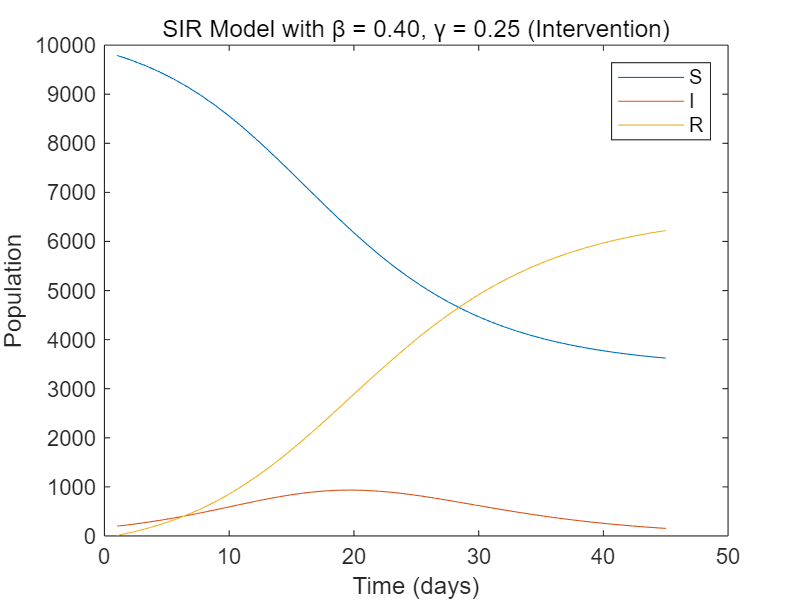

% Parameters
beta3 = 0.40;
gamma3 = 0.25;

% Simulate
[t3,Y3] = ode45(@(t,Y) simple_SIR(t,Y,beta3,gamma3), [1 45], Y0);

% Plot
figure;
plot(t3, Y3(:,1), t3, Y3(:,2), t3, Y3(:,3));
xlabel('Time (days)');
ylabel('Population');
legend('S', 'I', 'R');
title('SIR Model with β = 0.40, γ = 0.25 (Intervention)');

This shows that the infected population grows initially and then declines as individuals recover at a higher rate. 

## IV. Introducing Randomness

In the earlier scenario, we assumed that the infection and recovery rates were constant, which is not entirely realistic. For example, the rate of infection is influenced by various factors such as mask usage, proximity, the health condition of individuals, and more. Instead of introducing new variables to account for these uncertainties, we incorporate randomness into our model to capture these fluctuating elements. Here, we consider the infection rate as a random variable ranging from 30% to 90%, and the recovery rate as a random variable spanning from 10% to 30%. Both rates follow a uniform distribution within their respective ranges.

#### Codes & Figure:

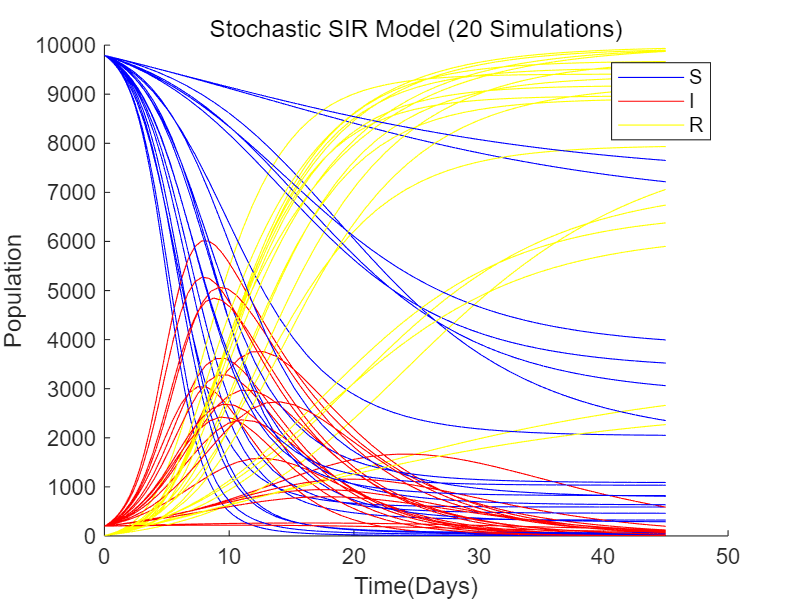

% Initial Conditions
N = 10000;
S0 = 9790;
I0 = 200;
R0 = 10;
Y0 = [S0; I0; R0];
tspan = [0 45];

figure;
hold on;

for i = 1:20

    % Random parameters for each simulation
    beta_random = 0.3 + (0.9 - 0.3) * rand;
    gamma_random = 0.1 + (0.3 - 0.1) * rand;

    % Run simulation
    [t,Y] = ode45(@(t,Y) simple_SIR(t,Y,beta_random,gamma_random), tspan,Y0);

    % Plot
    p1 = plot(t, Y(:,1),'b');
    hold on
    p2 = plot(t, Y(:,2),'r');
    p3 = plot(t, Y(:,3),'y');

end
xlabel('Time(Days)');
ylabel('Population');
title('Stochastic SIR Model (20 Simulations)');
legend('S', 'I', 'R');
hold off;

### Analysis: 

The 20 simulations demonstrate how different randomly selected infection and recovery rates can produce different outbreak dynamics under the same initial conditions. Some simulations show earlier and higher infection peaks, while others peak later or remain more moderate. 

In some cases, a larger portion of the population remains susceptible because of lower transmission or faster recovery. The final number of recovered individuals also varies across simulations, showing how changes in model parameters can affect epidemic outcomes. This stochastic approach provides a simple way to represent uncertainty in infection and recovery rates.

## V. Application in Arizona

The provided file “ArizonaData.mat” records the COVID-19 data in Arizona from 5/23/20 to 8/30/20: column 1 – daily new cases; column 2 – total death. For simplicity, we assume this COVID-19 pandemic happened in an area with a total of 50,000 population (fixed). In the initial SIR analysis, deaths are not considered. 

#### Codes & Figure: 

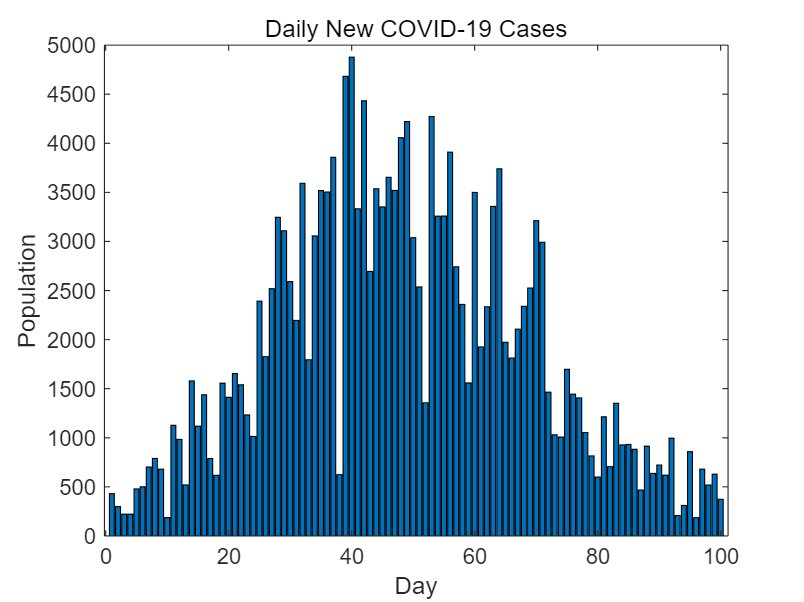

%% Arizona Data
load('ArizonaData.mat');
daily_new_cases = ArizonaData(:,1);

% Plot the bar graph
bar(1:100,daily_new_cases);
xlabel('Day');
ylabel('Population');
title('Daily New COVID-19 Cases');

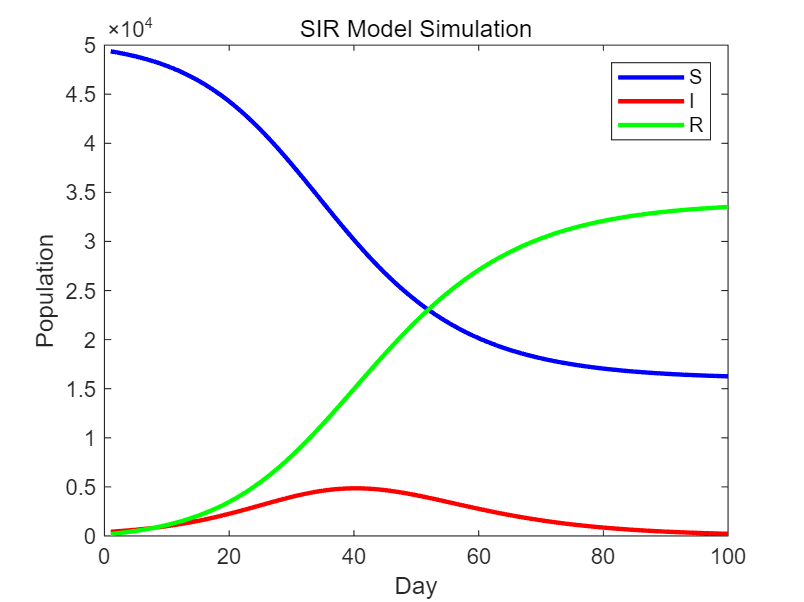

% Initial Conditions
N = 50000;
I0 = 431;
R0 = 200;
S0 = N - I0 - R0;
Y0 = [S0;I0;R0];
tspan = 0:99;
beta = 0.25;
gamma = 0.15;

% Run SIR Simulation
[t, Y] = ode45(@(t,Y) simple_SIR(t,Y,beta,gamma), tspan, Y0);

% Plot SIR Model
S = Y(:,1);
I = Y(:,2);
R = Y(:,3);
plot(t+1, S, 'b', t+1, I, 'r', t+1, R, 'g', 'LineWidth', 2);
xlabel('Day'); ylabel('Population');
title('SIR Model Simulation');
legend('S', 'I', 'R');

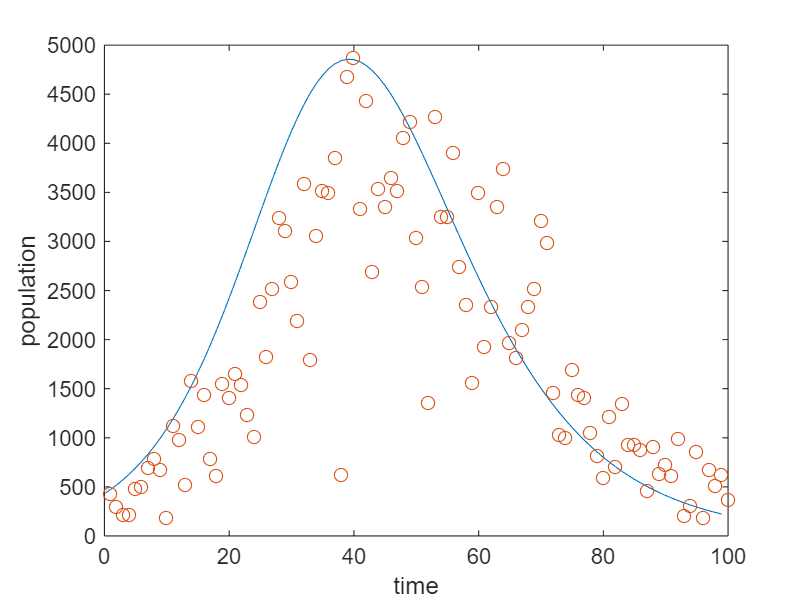

% Compare SIR model with Arizona COVID-19 Data

tdata = 1:1:100;
case_number = ArizonaData(:,1);

[t,Y] = ode45(@(t,Y) simple_SIR(t,Y,beta,gamma),tspan,Y0);

plot(t,Y(:,2));
hold on
scatter(tdata,case_number);
hold off
xlabel('time');
ylabel('population');

% fitting-error
fitting_err_1 = calculate_fitting_error(0.25, 0.13, case_number, tspan, Y0, tdata, N);
disp(fitting_err_1');

   1.0e+03 *

         0    0.1843    0.3218    0.3883    0.2054    0.2658    0.1563    0.1698    0.3910    1.0089    0.2052    0.4986    1.1249    0.2434    0.8959    0.7846    1.6569    2.0665    1.3816    1.7922    1.8289    2.2317    2.8354    3.3566    2.2829    3.1504    2.7548    2.3144    2.7242    3.4964    4.1264    2.9386    4.9174    3.8061    3.4610    3.5595    3.2553    6.5036    2.4301    2.1871    3.6532    2.4478    4.0556    3.0624    3.0753    2.5872    2.5200    1.7722    1.3893    2.3479    2.6211    3.5720    0.4276    1.2175    0.9926    0.1230    1.0778    1.2536    1.8531    0.2812    1.1070    0.5199    0.6724    1.2179    0.3945    0.4076    0.0258    0.3897    0.7004    1.5051    1.3960    0.0266    0.3633    0.2929    0.4839    0.3113    0.3496    0.0691    0.1021    0.2555    0.4170    0.0364    0.6597    0.2834    0.3340    0.3256    0.0507    0.4324    0.1881    0.3054    0.2306    0.6348    0.1278    0.0012    0.5688    0.0838    0.4292    0.2859    0.

fitting_err_2 = calculate_fitting_error(0.24, 0.15, case_number, tspan, Y0, tdata, N);
disp(fitting_err_2');

   1.0e+03 *

         0    0.1700    0.2904    0.3361    0.1286    0.1601    0.0166    0.0094    0.1663    0.7317    0.1318    0.0938    0.6437    0.3229    0.2349    0.0192    0.7770    1.0621    0.2433    0.5114    0.3980    0.6446    1.0875    1.4452    0.2078    0.9145    0.3643    0.2221    0.0533    0.7054    1.2319    0.0404    1.8755    0.7242    0.3626    0.4677    0.1926    3.4917    0.5107    0.6640    0.9085    0.1762    1.5639    0.7119    0.8724    0.5358    0.6218    0.0273    0.2040    0.9027    1.3194    2.4079    0.6057    0.3076    0.1986    0.5627    0.4924    0.7608    1.4451    0.6119    0.8463    0.3223    0.8134    1.3083    0.3488    0.4014    0.0027    0.3312    0.6160    1.3986    1.2708    0.1673    0.5169    0.4568    0.3118    0.1330    0.1668    0.1166    0.2892    0.4430    0.2302    0.2216    0.4767    0.1033    0.1573    0.1527    0.2193    0.2683    0.0287    0.1510    0.0812    0.4905    0.2671    0.1354    0.4397    0.2078    0.3102    0.1717    0.

fitting_err_3 = calculate_fitting_error(0.24, 0.13, case_number, tspan, Y0, tdata, N);
disp(fitting_err_3');

   1.0e+03 *

         0    0.1795    0.3113    0.3706    0.1792    0.2294    0.1079    0.1072    0.3121    0.9109    0.0854    0.3539    0.9521    0.0394    0.6569    0.5072    1.3373    1.7013    0.9678    1.3273    1.3109    1.6595    2.2088    2.6761    1.5507    2.3701    1.9315    1.4541    1.8343    2.5851    3.2029    2.0127    3.9997    2.9071    2.5908    2.7273    2.4694    5.7713    1.7576    1.5794    3.1141    1.9795    3.6590    2.7370    2.8194    2.3985    2.3953    1.7078    1.3812    2.3914    2.7115    3.7044    0.5971    1.4193    1.2224    0.3766    1.3512    1.5430    2.1551    0.0302    1.4250    0.8419    0.3486    0.8943    0.7162    0.7258    0.2878    0.0820    0.3995    1.2117    1.1108    0.3031    0.6309    0.5514    0.2347    0.0716    0.1193    0.1518    0.3136    0.4578    0.2237    0.2209    0.4838    0.1158    0.1745    0.1738    0.1949    0.2955    0.0582    0.1822    0.1139    0.5242    0.2325    0.1003    0.4750    0.1724    0.3454    0.2068    0.

## VI. Improvement

Now, we introduce "Death" as a variable in our SIR model. 

#### We define: 

- $D\left(t\right)$ = total number of deaths at time 𝑡 , 𝛿 is the death rate. 

- 
$$\frac{\mathrm{d}}{\mathrm{d}t}D=\delta I$$


#### We assume:

- N = 50000 

- 
$$\beta =0\ldotp 22$$


- 
$$\gamma =0\ldotp 12$$


- 
$$\Delta =0\ldotp 016$$


- 
$$I_0 =100$$


- 
$$R_0 =200$$


- 
$$D_0 =10$$


#### Codes:

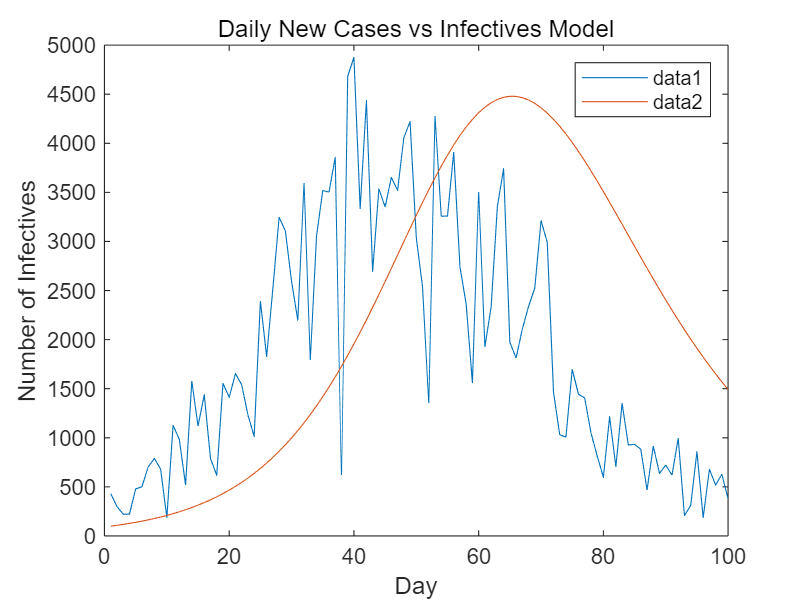

% Initial Condition
N = 50000;
I0 = 100;   
R0 = 200;   
D0 = 10;    
S0 = N - I0 - R0 - D0;
beta = 0.22;
gamma = 0.12;
delta = 0.016;
Y0 = [S0; I0; R0; D0];
tspan = 1:100;

% Run simulation
[t, Y] = ode45(@(t,Y) simple_SIRD(t,Y,beta,gamma,delta,N), tspan, Y0);


I_sim = Y(:,2);  
D_sim = Y(:,4);  

% Plot daily new cases vs infectives
figure;
plot(tspan, daily_new_cases);
hold on;
plot(tspan, I_sim);
xlabel('Day');
ylabel('Number of Infectives');
title('Daily New Cases vs Infectives Model');
legend;

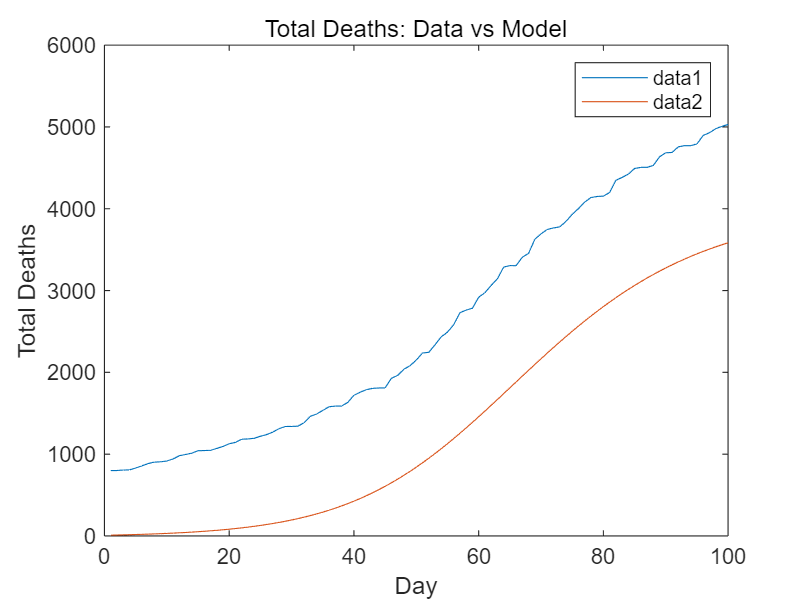

% Plot total death cases
figure;
total_deaths_data = ArizonaData(:,2);
plot(tspan, total_deaths_data);
hold on;
plot(tspan, D_sim);
xlabel('Day');
ylabel('Total Deaths');
title('Total Deaths: Data vs Model');
legend;

% fitting error
fitting_err_infectives = mean(abs(I_sim - daily_new_cases));
fitting_err_deaths = mean(abs(D_sim - total_deaths_data));

disp(fitting_err_infectives)

   1.4339e+03



disp(fitting_err_deaths)

   1.2506e+03



## VII. Reflection

Over the course of learning the SIR model, I've learned how the population can be divided into different parts (S, I, R) to visualize the dynamics of infectious disease spread. The model uses differential equations to describe the rates of change between these groups based on infection and recovery rates. One key insight is how disease outbreaks can grow or decline depending on these parameters.

Numerical simulations, like using MATLAB's `ode45`, allow us to visualize the trends over time and test how different parameters or interventions affect outcomes. These simulations make abstract equations more concrete and help in planning disease control strategies such as vaccination. 

However, the basic SIR model has several limitations. First, it assumes a fixed population with no births, deaths (except from disease), or migration, which is unrealistic in many real-world scenarios. Second, it assumes constant parameters (like infection rate), while in reality, these can change due to public health measures or behavior changes. To improve the model, we could extend it by incorporating factors such as age structure, contact networks, or time-varying parameters based on data or interventions. 

## VIII. References

Rai B, Shukla A, Dwivedi LK. Covid19 in India; predictions, reproduction number and public health preparedness. med Rxiv. 2020 doi: 10.1101/2020.04.09.20059261.

Oliveira Roster, Kirstin. *Introduction to SIR Modeling*. 12th Annual Workshop to Increase Diversity in Mathematical Modeling and Public Health, Harvard T.H. Chan School of Public Health, n.d.

He, Changhan. *Math 9 Final Project Review*. Department of Mathematics, University of California, Irvine, 6 June 2025. [www.changhanhe.com](http://www.changhanhe.com).

## IX. Define Functions

%% Simple SIR Function

function output = simple_SIR(~, Y, beta, gamma)

    % susceptible population differential equation
    dS = -beta*(Y(1)/(Y(1) + Y(2) + Y(3)))*Y(2);

    % infected population diffferential equation
    dI = beta*(Y(1)/(Y(1) + Y(2) + Y(3)))*Y(2) - gamma*Y(2);

    % recovered population differential equation
    dR = gamma*Y(2); 
    
    output = [dS; dI; dR];

end



%% Random Simple SIR Function

function output = simple_SIR_2(~,Y)

    % Random parameters
    beta = 0.3 + (0.9 - 0.3) * rand;   % between 0.3 and 0.9
    gamma = 0.1 + (0.3 - 0.1) * rand;  % between 0.1 and 0.3

    % susceptible population differential equation
    dS = -beta*(Y(1)/(Y(1) + Y(2) + Y(3)))*Y(2);

    % infected population diffferential equation
    dI = beta*(Y(1)/(Y(1) + Y(2) + Y(3)))*Y(2) - gamma*Y(2);

    % recovered population differential equation
    dR = gamma*Y(2); 
    
    output = [dS; dI; dR];

end


% fitting error
function fitting_err = calculate_fitting_error(beta, gamma, case_number, tspan, Y0, tdata, N)
    
    SIR_model = @(t, Y) simple_SIR(t, Y, beta, gamma);
    [t, Y] = ode45(SIR_model, tspan, Y0);
    I_sim = Y(:,2);
    fitting_err = abs(I_sim - case_number);  
end


% Improvement
function output = simple_SIRD(t,Y,beta,gamma,delta,N)

    S = Y(1);
    I = Y(2);
    R = Y(3);
    D = Y(4);

    dS = -beta*(Y(1)/(Y(1) + Y(2) + Y(3)))*Y(2);

    dI = beta*(Y(1)/(Y(1) + Y(2) + Y(3)))*Y(2) - gamma*Y(2) - delta*Y(2);

    dR = gamma*Y(2); 

    dD = delta*Y(2);

    output = [dS;dI;dR;dD];

end